This script serves to perform the required calibration needed to convert the radar permittivity to pseudoRAW values that allow us to use the TEROS 12 calibration process for various soil types.

c=299792458;                    % Speed of light (m/s)
resolution = 0.003790984152165; % Range resolution (m)

runName = {};
radarPermittivity = [];
expectedRAW = [];

`Ground truth data stored in `

[`https://docs.google.com/spreadsheets/d/1K78VeHgP5uEu7g3LeU7YA1ABJxbuOkrdziNVeoTXbkk/edit?usp=sharing`](https://docs.google.com/spreadsheets/d/1K78VeHgP5uEu7g3LeU7YA1ABJxbuOkrdziNVeoTXbkk/edit?usp=sharing)

`Starting with the dry run`

databaseName = '/data/chi-run-1/DryRun';
tag1Hz = 64;
tag2Hz = 105;

results = RunDualTagDataset(databaseName, tag1Hz, tag2Hz, false);
peakDifference = results.('Peak Difference');

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(3.28e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity = [radarPermittivity; radar_perm];
expectedRAW = [expectedRAW; ones(length(radar_perm), 1) * TEROS_raw];

`Second run`

databaseName = '/data/chi-run-2';
tag1Hz = 64;
tag2Hz = 105;

results = RunDualTagDataset(databaseName, tag1Hz, tag2Hz, false);
peakDifference = results.('Peak Difference');
peakDifference(2) = [];
peakDifference(4) = [];
peakDifference(4) = [];
peakDifference(5) = [];
peakDifference(5) = [];
peakDifference(5) = [];    % Major outliers due to a dual peak. This wasn't 
                            % existent in other datasets so must've been a
                            % result of improper alignment.

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(15.45e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity = [radarPermittivity; radar_perm];
expectedRAW = [expectedRAW; ones(length(radar_perm), 1) * TEROS_raw];

`Third run (something is off about this)`

% databaseName = '/data/chi-run-3';
% tag1Hz = 64;
% tag2Hz = 105;
% 
% peakDifference = RunDualTagDataset2(databaseName, tag1Hz, tag2Hz, true);
% 
% distance = 2/39.37;                         % Distance between tags (m)
% t = ((peakDifference + ...
%     distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
% radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity
% 
% TEROS_raw = 2031.86;                        % Taken from TEROS sensor readings
% 
% % Appending data to results table
% runName(end+1) = {databaseName};
% radarPermittivity(end+1) = radar_perm;
% expectedRAW(end+1) = TEROS_raw;


Fourth run

databaseName = '/data/chi-run-4';
tag1Hz = 64;
tag2Hz = 105;

results = RunDualTagDataset(databaseName, tag1Hz, tag2Hz, false);
peakDifference = results.('Peak Difference');

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(21.58e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity = [radarPermittivity; radar_perm];
expectedRAW = [expectedRAW; ones(length(radar_perm), 1) * TEROS_raw];

Fifth run

databaseName = '/data/chi-run-5';
tag1Hz = 64;
tag2Hz = 105;

results = RunDualTagDataset(databaseName, tag1Hz, tag2Hz, false);
peakDifference = results.('Peak Difference');

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(21.90e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity = [radarPermittivity; radar_perm];
expectedRAW = [expectedRAW; ones(length(radar_perm), 1) * TEROS_raw];

Sixth run

databaseName = '/data/chi-run-6';
tag1Hz = 64;
tag2Hz = 105;

results = RunDualTagDataset(databaseName, tag1Hz, tag2Hz, false);
peakDifference = results.('Peak Difference');

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(25.12e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity = [radarPermittivity; radar_perm];
expectedRAW = [expectedRAW; ones(length(radar_perm), 1) * TEROS_raw];

Final stuff.

% Final table of results
% results = table(transpose(runName), transpose(radarPermittivity), transpose(expectedRAW), ...
%     'VariableNames', {'Run Name', 'Radar Permitivvity', 'Expected Raw'});

disp(results)

        Capture Name        64 Hz Peak Bin    64 Hz SNR (dB)    105 Hz Peak Bin    105 Hz SNR (dB)    Peak Difference
    ____________________    ______________    ______________    _______________    _______________    _______________

    {'chinotop1.frames'}         162               26.78              334              9.7797               172      
    {'chinotop2.frames'}         160              27.389              327              10.537               167      
    {'chinotop3.frames'}         159               27.61              324              10.401               165      



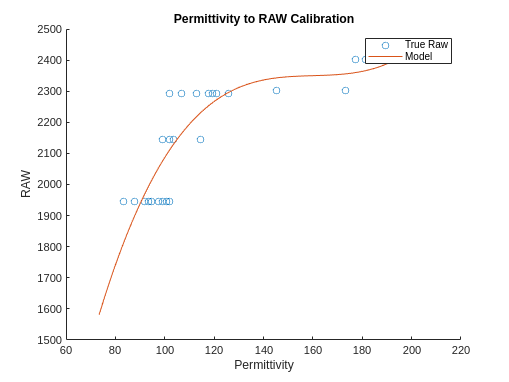


permittivity2raw = polyfit(radarPermittivity, expectedRAW, 3);

figure
scatter(radarPermittivity, expectedRAW)
hold on
radarPermittivityPoints = linspace(min(radarPermittivity) - 10, max(radarPermittivity) + 10, 100);
plot(radarPermittivityPoints, polyval(permittivity2raw, radarPermittivityPoints))
legend(["True Raw", "Model"])
xlabel("Permittivity")
ylabel("RAW")
title("Permittivity to RAW Calibration")

And results.

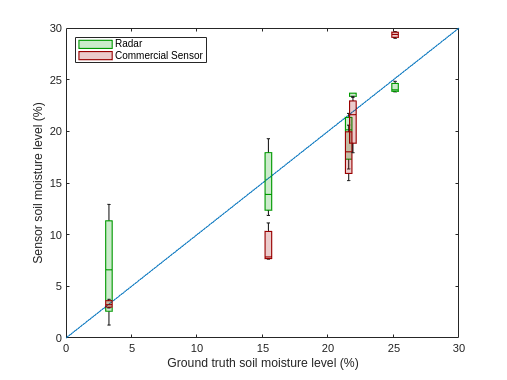

figure
x = linspace(0, 30, 100);
y = x;
plot(x, y); hold on

groundTruth = 100 .*[3.28e-2 15.45e-2 21.58e-2 21.90e-2 25.12e-2];

terosDataPoints = [3.22 3.74 2.91;
    7.63 7.84 11.14;
    18.02 20.60 15.23;
    23.39 17.93 21.61;
    29.38 29.66 29.00
    ];

radarDataPoints = [116 121 113;
    122 130 120;
    137 132 125;
    163 163 148;
    172 167 165]; % Got this by running RunDualTagDataset('/data/chi-run-6', 64, 105, false) 
                  % on all the datasets because the calibration process
                  % (RunDualTagDataset2) sums all the frames together to
                  % get the highest SNR. These are more realistic data points.
            
                  
distance = 2/39.37;                         % Distance between tags (m)
t = ((radarDataPoints + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

radarDataPoints = polyval(permittivity2raw, radar_perm);
radar_farmcalibrated = (5.12018081e-10)*radarDataPoints.^3 - (0.000003854251138)*radarDataPoints.^2 + (0.009950433112)*radarDataPoints - 8.508168835941; % Using Soil Calibration for UCSC Soil

for i = 1:length(groundTruth) % chaos...
    if i == 1
        b = boxchart(ones(1,3) * groundTruth(i), radar_farmcalibrated(i,:) * 100, ...
                     'BoxWidth', 0.5, 'DisplayName', "Radar");
        t = boxchart(ones(1,3) * groundTruth(i), terosDataPoints(i,:), ...
                     'BoxWidth', 0.5, 'DisplayName', "Commercial Sensor");
        firstBox = b;
        secondBox = t;
    else
        b = boxchart(ones(1,3) * groundTruth(i), radar_farmcalibrated(i,:) * 100, ...
                     'BoxWidth', 0.5);
        t = boxchart(ones(1,3) * groundTruth(i), terosDataPoints(i,:), ...
             'BoxWidth', 0.5);
    end
    b.BoxFaceColor = [0 0.6 0];  % Set green
    t.BoxFaceColor = [0.6 0 0];  % Set green
end

xlabel("Ground truth soil moisture level (%)")
ylabel("Sensor soil moisture level (%)")

legend([firstBox secondBox], 'Location', 'northwest');


% boxplot(radar_farmcalibrated'*100, groundTruth)
% Optional: move boxplot to top layer if needed
% children = get(gca, 'Children');
% set(gca, 'Children', flipud(children));
% boxplot(radar_farmcalibrated(1, :)*100, groundTruth(1))
% boxplot(radar_farmcalibrated(2, :)*100, groundTruth(2))